clc; clear; close all;
data = readtable('arm_workspace_points.csv');
data = data(data.theta3_deg < 175, :); %filter out one specific elbow config
inputs = [data.x_mm, data.y_mm, data.z_mm, data.q4_mm]'; %fix q4 to one input value
targets = [data.theta1_deg, data.theta2_deg, data.theta3_deg]';
size(inputs)

ans =            4       18924


size(targets)

ans =            3       18924


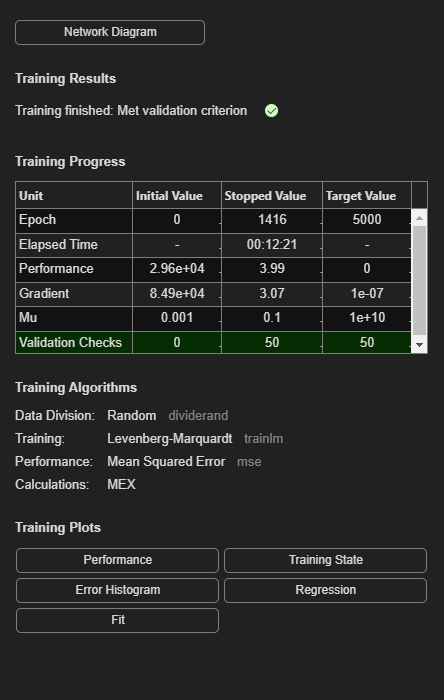

net = fitnet([25 25], 'trainlm'); %kept failing accuracy

net.divideFcn = 'dividerand';
net.divideParam.trainRatio = 0.70;
net.divideParam.valRatio = 0.15;
net.divideParam.testRatio = 0.15;

net.performFcn = 'mse';
net.trainParam.epochs = 5000;
net.trainParam.max_fail = 50; % kept stopping early

[net,tr] = train(net,inputs,targets);


predicted = net(inputs);
testInd = tr.testInd;
actualTest = targets(:,testInd);
predictedTest = predicted(:,testInd);

error = actualTest - predictedTest;
RMSE = sqrt(mean(error.^2,2));
MAE = mean(abs(error),2);
R2 = 1 - sum(error.^2,2) ./ sum((actualTest-mean(actualTest,2)).^2,2);

fprintf('THETA1 RMSE = %.4f deg\n',RMSE(1));

THETA1 RMSE = 6.1593 deg


fprintf('THETA2 RMSE = %.4f deg\n',RMSE(2));

THETA2 RMSE = 1.6448 deg


fprintf('THETA3 RMSE = %.4f deg\n',RMSE(3));

THETA3 RMSE = 1.8859 deg


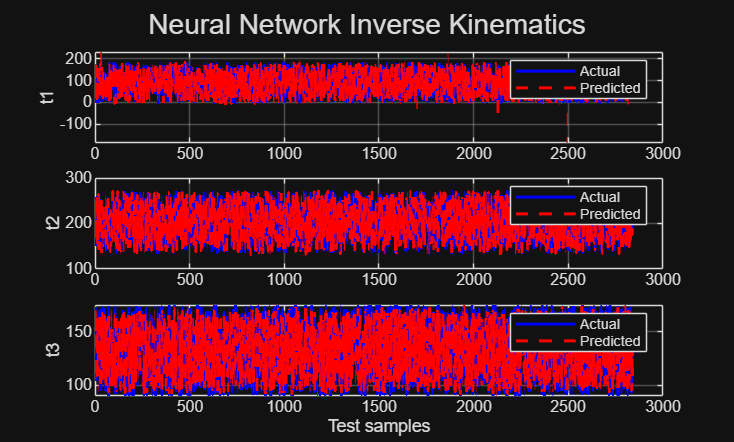

figure;
names = {'t1','t2','t3'};
for i = 1:3
subplot(3,1,i);
plot(actualTest(i,:),'b','LineWidth',1.5);
hold on;
plot(predictedTest(i,:),'r--','LineWidth',1.5);
ylabel(names{i});
legend('Actual','Predicted');
grid on;
end
xlabel('Test samples');
sgtitle('Neural Network Inverse Kinematics');

newPosition = inputs(:,testInd(1));
newAngles = net(newPosition);
trueAngles = targets(:,testInd(1));
fprintf('\nPredicted vs true:\n');


Predicted vs true:


fprintf('theta1 = %.4f  (true %.4f)\n',newAngles(1),trueAngles(1));

theta1 = 115.3503  (true 113.8247)


fprintf('theta2 = %.4f  (true %.4f)\n',newAngles(2),trueAngles(2));

theta2 = 180.8273  (true 179.0751)


fprintf('theta3 = %.4f  (true %.4f)\n',newAngles(3),trueAngles(3));

theta3 = 170.0108  (true 173.2298)


save('Inverse_Kinematics_Model.mat','net','tr');